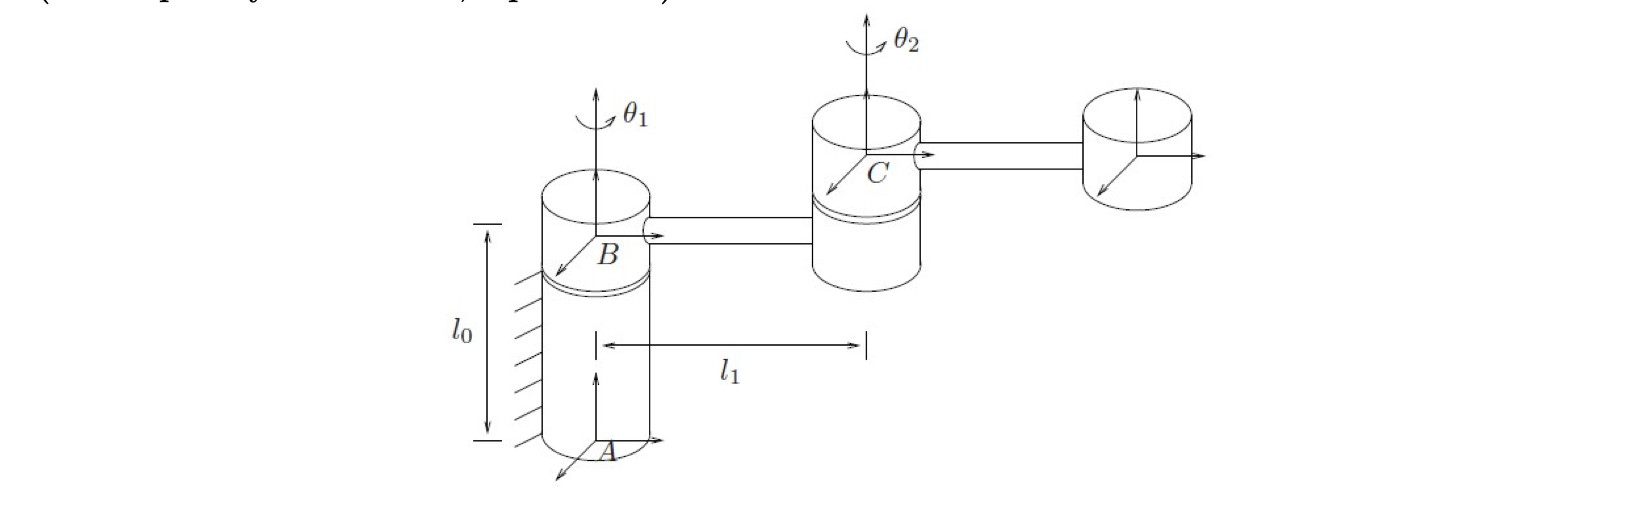

import robo.*
syms t l_0 l_1 theta1 real
syms theta1(t) theta2(t)
theta2

$$theta2(t) = \theta_{2}\left(t\right)$$


% 2. 构造单位列向量 u = [0; 0; 1]
u = [0; 0; 1];

% 3. 罗德里格斯旋转矩阵：绕 u 转 theta1、theta2
exphutheta1 = rodrigues(u,theta1);
exphutheta2 = rodrigues(u,theta2);

% 4. 显示结果
exphutheta2

$$exphutheta2(t) = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

The next two code cells calculate the initial configuratons of frames 𝐵 and 𝐶, 𝑔𝑎𝑏(0) and 𝑔𝑏𝑐(0),

respectively, with the function gmat. The function gmat is not a standard Python function, but

one developed by myself, in my file robotics_functions_sym.py. I do not make this avaiable to

students, as students need to develop their own utility functions like this. The function gmat packs

its input variables into a homogeneous representation of the rigid body displacement transformation

as in MLS equation (2.23) p. 36 and returns the resulting 𝑔 matrix to the calling program.

In the initial configurations, 𝜃1 = 𝜃2 = 0 and hence the rotation matrices are both identity matrices.

p_ab0 = [0;0;l_0]

$$p\_ab0 = \left(\begin{array}{c} 0\\ 0\\ l_{0} \end{array}\right)$$

gab0 = gmat(eye(3),p_ab0); % 使用g_mat这个函数要求 p_ab0一定要是3*1的平移向量
gab0

$$gab0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

p_bc0 = [0;l_1;0]

$$p\_bc0 = \left(\begin{array}{c} 0\\ l_{1}\\ 0 \end{array}\right)$$

gbc0 = gmat(eye(3),p_bc0);
gbc0

$$gbc0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$\textrm{𝑔𝑎𝑏}\left(\textrm{𝜃1}\right)=\textrm{𝑒̂}\textrm{𝜉1𝜃1}\textrm{𝑔𝑎𝑏}\left(0\right)$$



$$\textrm{𝑔𝑏𝑐}\left(\textrm{𝜃2}\right)=\textrm{𝑒̂}\textrm{𝜉2𝜃2}\textrm{𝑔𝑏𝑐}\left(0\right)$$


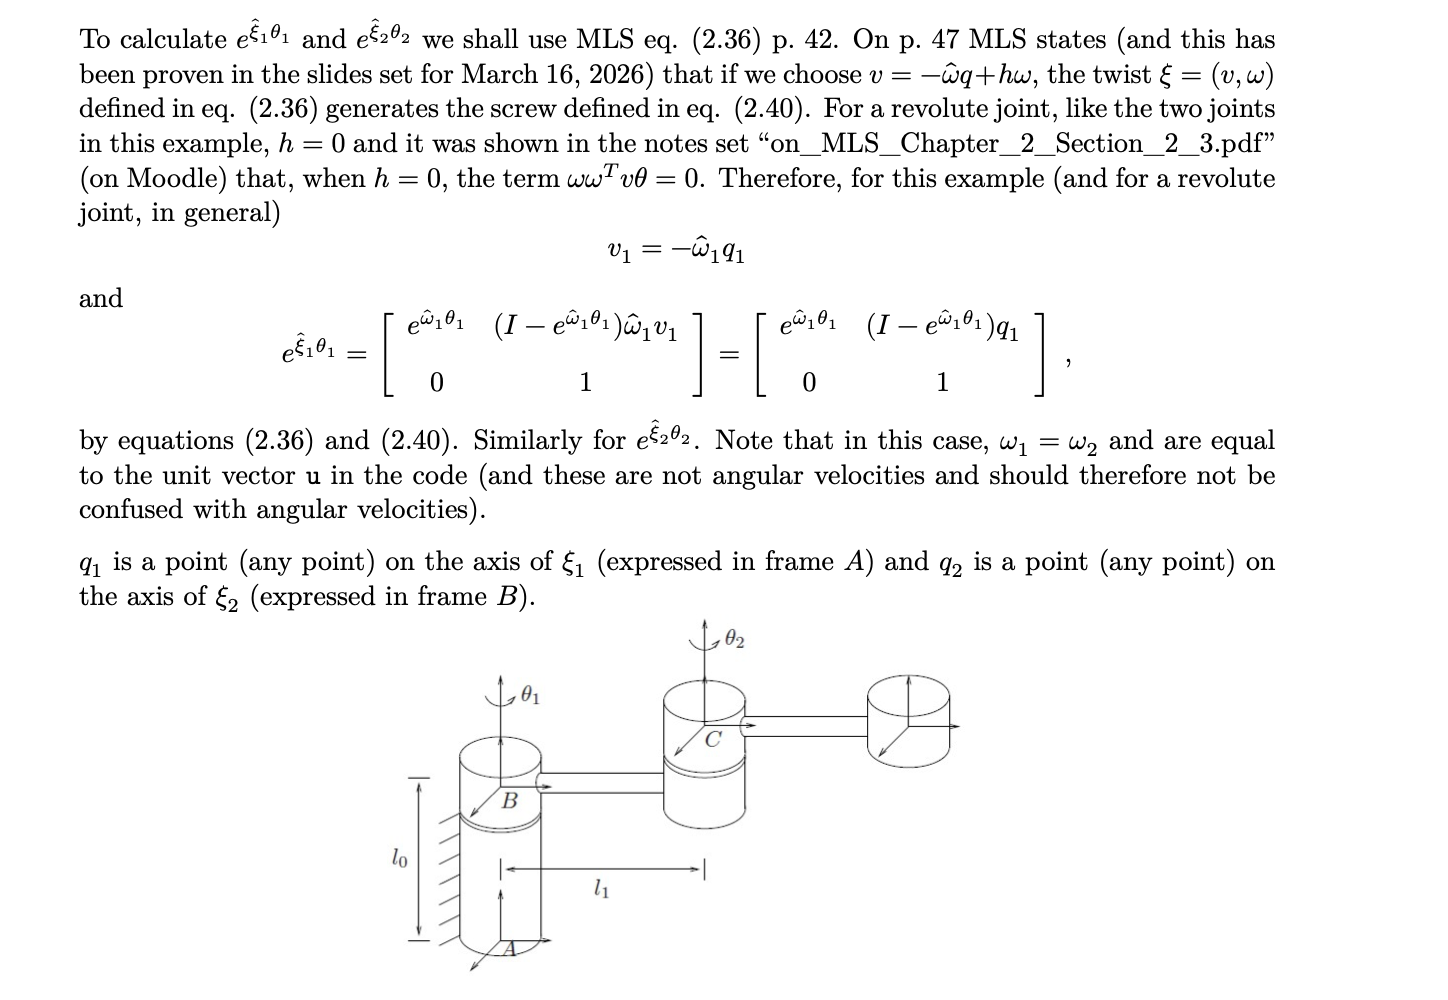

%下面是关于 velocity的公式
q1 = [0;0;0];
q2 = [0;l_1;0];

v1 = -hatm_sym(u)* q1

v1 =      0
     0
     0


v2 = -hatm_sym(u) * q2

$$v2 = \left(\begin{array}{c} l_{1}\\ 0\\ 0 \end{array}\right)$$


% 纵向拼接 = BlockMatrix([[v1],[u]])
xi1 = [v1; u]

xi1 =      0
     0
     0
     0
     0
     1


twistexp1 = [exphutheta1,(eye(3) - exphutheta1)*q1;
    zeros(1,3),1]

$$twistexp1(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

xi2 = [v2; u]

$$xi2 = \left(\begin{array}{c} l_{1}\\ 0\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

twistexp2 = [exphutheta2,(eye(3) - exphutheta2)*q2;
    zeros(1,3),1]

$$twistexp2(t) = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & l_{1}\,\sin\left(\theta_{2}\left(t\right)\right)\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & -l_{1}\,\left(\cos\left(\theta_{2}\left(t\right)\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

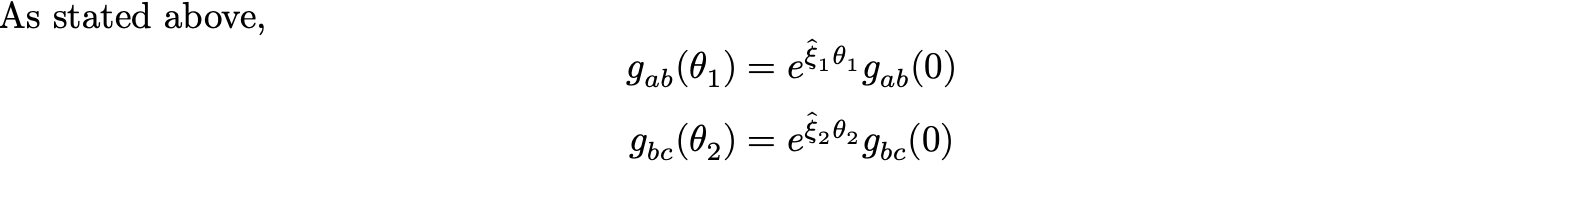

gab = twistexp1*gab0

$$gab(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

gbc = twistexp2*gbc0

$$gbc(t) = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & l_{1}\,\cos\left(\theta_{2}\left(t\right)\right)-l_{1}\,\left(\cos\left(\theta_{2}\left(t\right)\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

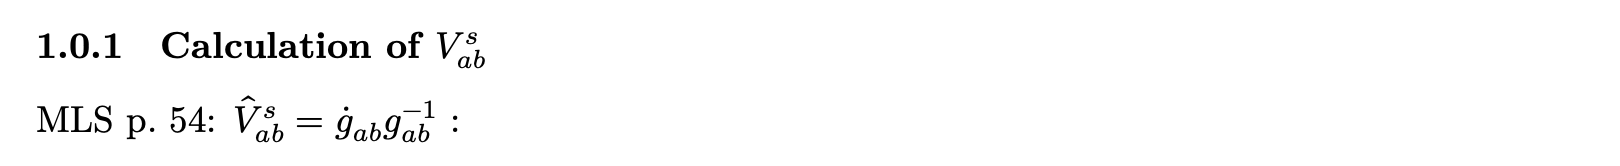

Vhatabs = simplify(diff(gab,t) * inv(gab)) %注意，矩阵求逆可以用这个 inv（）矩阵名字

$$Vhatabs(t) = \left(\begin{array}{cccc} 0 & -\frac{\partial }{\partial t}\theta_{1}\left(t\right) & 0 & 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

hat_xi1 = wedge(xi1)

hat_xi1 =      0    -1     0     0
     1     0     0     0
     0     0     0     0
     0     0     0     0


Vhatabs_2 = hat_xi1*diff(theta1,t)

$$Vhatabs\_2(t) = \left(\begin{array}{cccc} 0 & -\frac{\partial }{\partial t}\theta_{1}\left(t\right) & 0 & 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

shouldbezero = Vhatabs - Vhatabs_2;

Vabs = vee(Vhatabs)

$$Vabs = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$

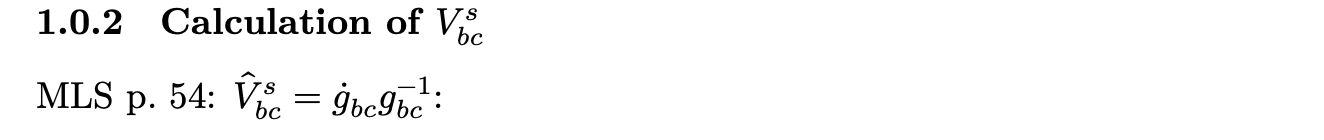

Vhatbcs = simplify((diff(gbc,t))* inv(gbc))

$$Vhatbcs(t) = \left(\begin{array}{cccc} 0 & -\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & l_{1}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Vbcs = vee(Vhatbcs)

$$Vbcs = \left(\begin{array}{c} l_{1}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

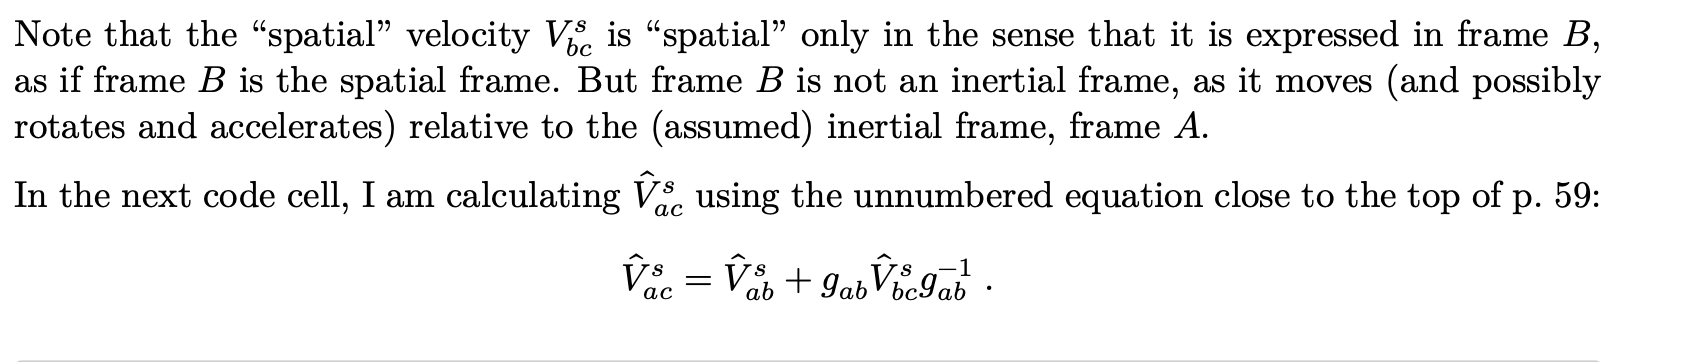

Vhatacs = simplify(Vhatabs + gab * Vhatbcs * inv(gab))

$$Vhatacs(t) = \left(\begin{array}{cccc} 0 & -\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & 0 & l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Vacs = vee(Vhatacs)

$$Vacs = \left(\begin{array}{c} l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

Ad_gab = simplify(Adgg(gab))

$$Ad\_gab = \begin{array}{l} \left(\begin{array}{cccccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & \sigma_{1} & -\sigma_{2} & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & \sigma_{2} & \sigma_{1} & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 0 & \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l_{0}\,\sin\left(\theta_{1}\left(t\right)\right)\\ \sigma_{2}=l_{0}\,\cos\left(\theta_{1}\left(t\right)\right) \end{array}$$

Vacs_2 = Vabs + Ad_gab*Vbcs

$$Vacs\_2 = \left(\begin{array}{c} l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)+\frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

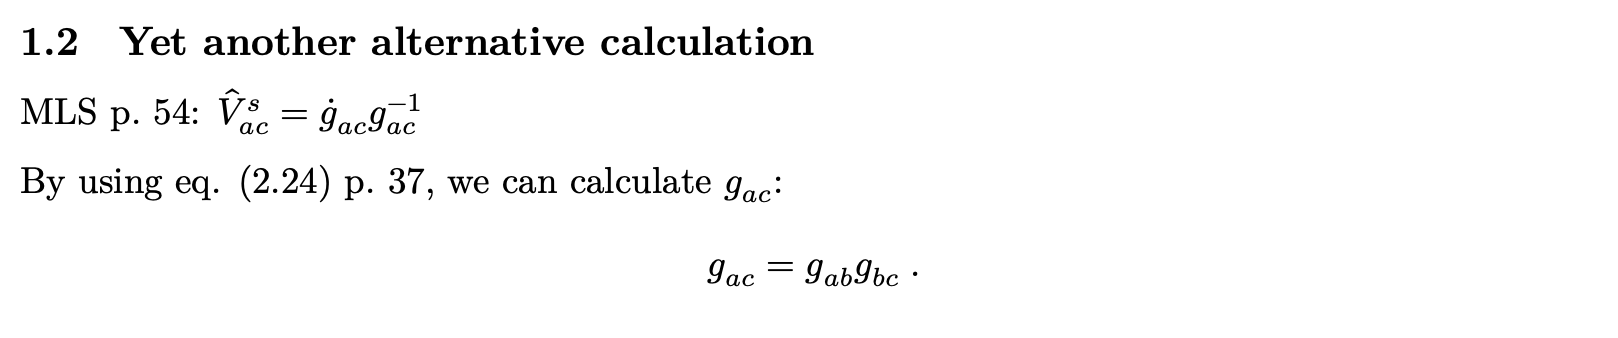

gac = gab * gbc

$$gac(t) = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)-\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right) & 0 & -\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}\\ \cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)+\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right) & \sigma_{1} & 0 & \cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{2}\\ 0 & 0 & 1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\\ \sigma_{2}=l_{1}\,\cos\left(\theta_{2}\left(t\right)\right)-l_{1}\,\left(\cos\left(\theta_{2}\left(t\right)\right)-1\right) \end{array}$$

Vhatacs2 = simplify(diff(gac,t) * inv(gac));
sholdbezero2 = Vhatacs - Vhatacs2

$$sholdbezero2(t) = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$